% 

clear variables
close all
clc

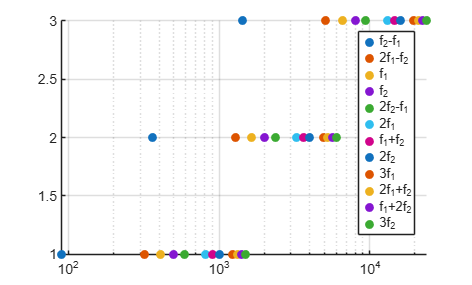


fs = 44100;
blockLength=4096;

fRatio = 1.22;

% f2aimOrig = [500:500:1500 2000:1000:10000].';
f2aimOct = [500 1000 2000 4000 8000]';
f2aim2Oct = [500 2000 8000]';

f2aim = f2aim2Oct;

freqFFT=(0:blockLength/2-1).'*fs/blockLength;

idxFreq=round((f2aim*blockLength/fs+1).*[1/fRatio 1]);
idxFreq(:,3)=2*idxFreq(:,1)-idxFreq(:,2);
freq=reshape(freqFFT(idxFreq),size(idxFreq));

fAim = f2aim.*[1/fRatio 1];
fAim(:,3) = 2*fAim(:,1)-fAim(:,2);
[dpAim, labels] = calcDPVector(fAim);

%%%%%% PLOT %%%%%%
s = length(f2aim);
y = zeros(s, 12);
for i = 1:s
    y(i,:) = i;
end
% c = linspace(1,m,m);
% stem(dpAim(:,1:end), y);
scatter(dpAim(:,1:end), y, 'filled');
set(gca,'xscale','log')
legend(labels);
% hold on

% axis([0 2e4 0 4])
grid on

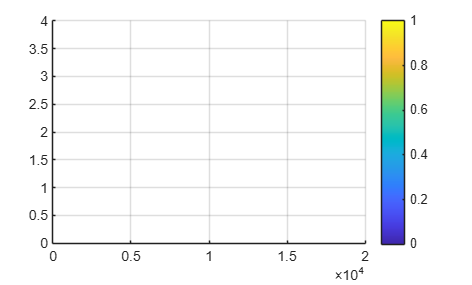

% colorbar
%%%% PLOT END %%%%

[dupes, dupeLoc] = findDupes(dpAim);
n = length(dupes);

dupePairs = zeros(3, n/2);
dupeLocPairs = zeros(2, n/2);
k_prev = 0;
for k = 1:n
    for l = k+1:n
        if dupes(k) == dupes(l) && k ~= l
            dupePairs(1,k) = dupes(k);
            if k == k_prev
                dupePairs(2,k) = dupePairs(2,k)+1;
            else
                dupePairs(2,k) = dupePairs(2,k)+2;
            end
            dupeLocPairs(1, k) = dupeLoc(k);
            dupeLocPairs(2, k) = dupeLoc(l);
            k_prev = k;
        end
    end
end


% dupePairs(:,any(dupePairs == 0))=[];
m = length(dupePairs(1,:));

%%%%%% PLOT %%%%%%
c = linspace(1,m,m);
scatter(dupePairs(1,:), dupePairs(2,:), [], c, "filled")
% stem(dupePairs(1,:), dupePairs(2,:), 'LineStyle', '-', 'Marker', 'o')
axis([0 2e4 0 4])
grid on
colorbar

%%%% PLOT END %%%%






%%%% FUNCTIONS %%%
function [dpVector, labels] = calcDPVector(freq)
dpVector = [freq(:,2)-freq(:,1), freq(:,3), freq(:,1), freq(:,2), 2*freq(:,2)-freq(:,1), 2*freq(:,1), freq(:,1)+freq(:,2), 2*freq(:,2), 3*freq(:,1), 2*freq(:,1)+freq(:,2), freq(:,1)+2*freq(:,2), 3*freq(:,2)];
labels = ["f_2-f_1", "2f_1-f_2", "f_1", "f_2", "2f_2-f_1", "2f_1", "f_1+f_2", "2f_2", "3f_1", "2f_1+f_2", "f_1+2f_2", "3f_2"];
end

function [dupes, dupeLoc] = findDupes(A)
[~, uniqueIdx] = unique(A);
dupeIdx = ismember( A, A( setdiff( 1:numel(A), uniqueIdx ) ) );
dupes = A(dupeIdx);
dupeLoc = find(dupeIdx);
end